### Load in data and compile

cd("C:\Users\djlasky\OneDrive - University of California, Davis\Documents\UC Davis\Usrey Lab\Analysis");
trialBlocks = 52;

trialCorrect    = cell(trialBlocks, 1);
trialValidity   = cell(trialBlocks, 1);
S1OnTime        = cell(trialBlocks, 1);
S1OffTime       = cell(trialBlocks, 1);

for n = 1:trialBlocks
    fileName = sprintf("DannyLinearS1_%d.mat", n);
    data = load(fileName);
    trialCorrect{n}     = data.trialCorrect;
    trialValidity{n}    = data.valid;
    S1OnTime{n}         = data.stim1OnsetTime;
    S1OffTime{n}        = data.stim1OffsetTime;
end

trialCorrect    = horzcat(trialCorrect{:});
trialValidity   = horzcat(trialValidity{:});
S1OnTime        = horzcat(S1OnTime{:});
S1OffTime       = horzcat(S1OffTime{:});

S1Timing = (S1OffTime - S1OnTime) * 1000;       % Convert to msec

validCorrect = trialCorrect(trialValidity == 1);
validS1 = S1Timing(trialValidity == 1);

myColor = flipud(winter);

### Plot windowed and zero-padded Fourier transform of valid trial hit rate with different Kastner averages

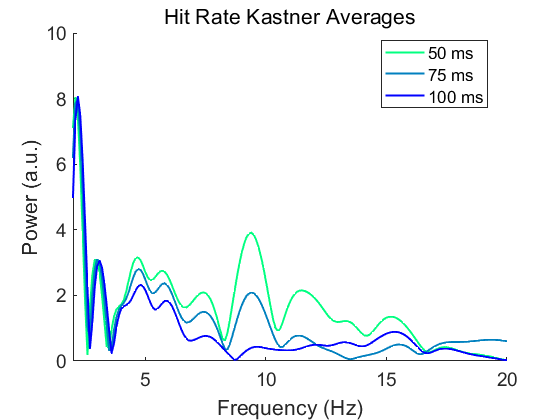

window50    = 500:1650;
window75    = 500:1625;
window100   = 500:1600;
hitRateKastner50    = nan(1150, 1);
hitRateKastner75    = nan(1125, 1);
hitRateKastner100   = nan(1100, 1);

for n = 1:1150
    windowTrials50 = validS1 >= window50(n) & validS1 <= window50(n) + 50;
    hitRateKastner50(n) = sum(validCorrect(windowTrials50), "all") / sum(windowTrials50, "all");
end

for n = 1:1125
    windowTrials75 = validS1 >= window75(n) & validS1 <= window75(n) + 75;
    hitRateKastner75(n) = sum(validCorrect(windowTrials75), "all") / sum(windowTrials75, "all");
end

for n = 1:1100
    windowTrials100 = validS1 >= window100(n) & validS1 <= window100(n) + 100;
    hitRateKastner100(n) = sum(validCorrect(windowTrials100), "all") / sum(windowTrials100, "all");
end

hitRateKastner50 = movmean(hitRateKastner50, 25);   % 25 point boxcar smoothing
hitRateKastner75 = movmean(hitRateKastner75, 25);
hitRateKastner100 = movmean(hitRateKastner100, 25);

hitRateKastner50Win = hitRateKastner50 .* hann(height(hitRateKastner50));
hitRateKastner75Win = hitRateKastner75 .* hann(height(hitRateKastner75));
hitRateKastner100Win = hitRateKastner100 .* hann(height(hitRateKastner100));

hitRateKastner50WinPad = [hitRateKastner50Win; zeros(8850, 1)];
hitRateKastner75WinPad = [hitRateKastner75Win; zeros(8875, 1)];
hitRateKastner100WinPad = [hitRateKastner100Win; zeros(8900, 1)];

FFT_hitRateKastner50 = fft(hitRateKastner50WinPad);
FFT_hitRateKastner75 = fft(hitRateKastner75WinPad);
FFT_hitRateKastner100 = fft(hitRateKastner100WinPad);

samplingFreqKastner = 1000;
signalLengthKastnerHP = height(hitRateKastner50WinPad);
xValsKastner = (0:(signalLengthKastnerHP - 1)) * samplingFreqKastner/signalLengthKastnerHP;       % Freq resolution = 0.1; (0:(signalLength - 1)) * (samplingFreq/signalLength)

figure
plot(xValsKastner, abs(FFT_hitRateKastner50), "Color", myColor(1,:), "LineWidth", 1.5)
hold on
plot(xValsKastner, abs(FFT_hitRateKastner75), "Color", myColor(128,:), "LineWidth", 1.5)
plot(xValsKastner, abs(FFT_hitRateKastner100),  "Color", myColor(256,:), "LineWidth", 1.5)
hold off
box off
xlim([2 20])
ax = gca;
ax.FontSize = 14;
xlabel("Frequency (Hz)", "FontSize", 16)
ylabel("Power (a.u.)", "FontSize", 16)
title("Hit Rate Kastner Averages", "FontSize", 16, "FontWeight", "normal")
legend(["50 ms", "75 ms", "100 ms"], "Location", "best")

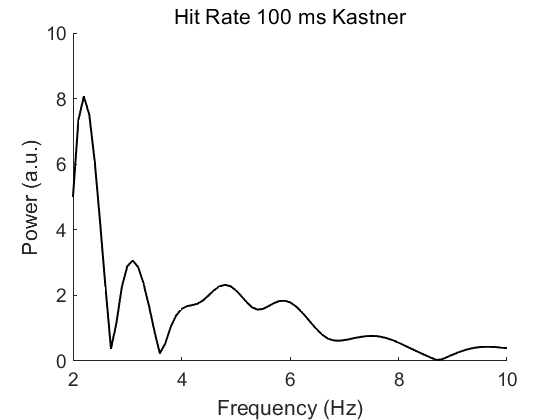


figure
plot(xValsKastner, abs(FFT_hitRateKastner100), "k", "LineWidth", 1.5)
box off
xlim([2 10])
ax = gca;
ax.FontSize = 14;
xlabel("Frequency (Hz)", "FontSize", 16)
ylabel("Power (a.u.)", "FontSize", 16)
title("Hit Rate 100 ms Kastner", "FontSize", 16, "FontWeight", "normal")

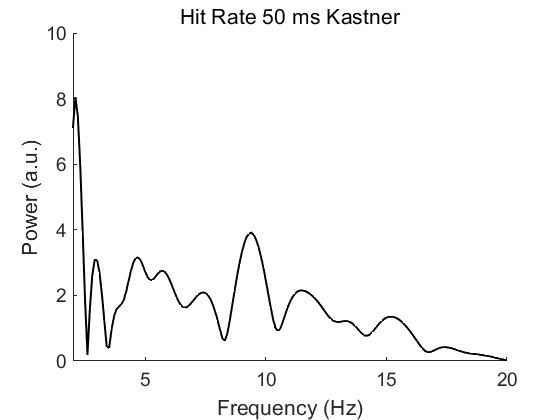


figure
plot(xValsKastner, abs(FFT_hitRateKastner50), "k", "LineWidth", 1.5)
box off
xlim([2 20])
ax = gca;
ax.FontSize = 14;
xlabel("Frequency (Hz)", "FontSize", 16)
ylabel("Power (a.u.)", "FontSize", 16)
title("Hit Rate 50 ms Kastner", "FontSize", 16, "FontWeight", "normal")

### Baseline for 50 ms Kastner hit rate through random permutations

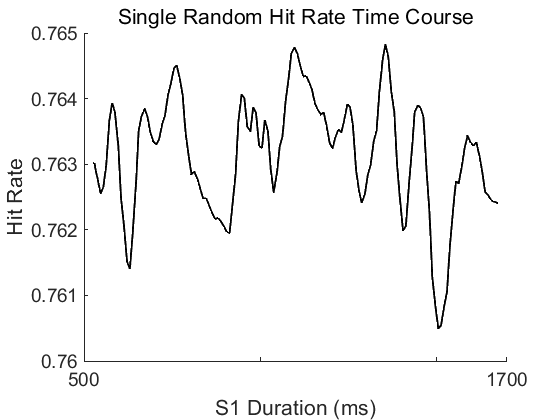

numPermutations = 1000;
hitRateKastner50Rand = nan(1150, numPermutations);

for m = 1:numPermutations
    randomCorrect = validCorrect(randperm(length(validCorrect)));
    for n = 1:1150
        windowTrials50 = validS1 >= window50(n) & validS1 <= window50(n) + 50;
        hitRateKastner50Rand(n, m) = sum(randomCorrect(windowTrials50), "all") / sum(windowTrials50, "all");
    end
end

hitRateKastner50Rand = movmean(hitRateKastner50Rand, 25, 1);   % 25 point boxcar smoothing
xValKastner50 = 526:1675;

figure
plot(xValKastner50, mean(hitRateKastner50Rand, 2), "k", "LineWidth", 1.5)
box off
xticks([500 1000 1500 1700])
xticklabels([500, "", "", 1700])
xlim([500 1700])
ax = gca;
ax.FontSize = 14;
title("Single Random Hit Rate Time Course", "FontSize", 16, "FontWeight", "normal")
xlabel("S1 Duration (ms)", "FontSize", 16)
ylabel("Hit Rate", "FontSize", 16)

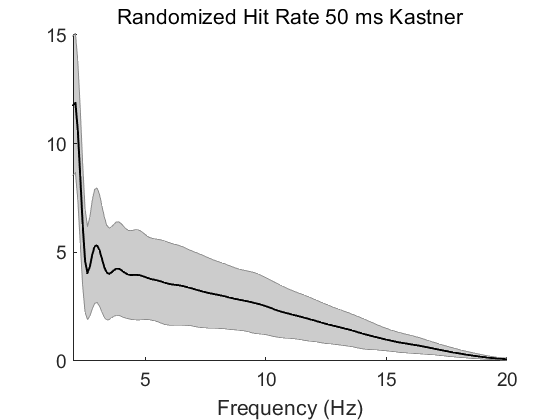


hitRateKastner50RandWin = hitRateKastner50Rand .* hann(height(hitRateKastner50Rand));
hitRateKastner50RandWinPad = [hitRateKastner50RandWin; zeros(8850, width(hitRateKastner50RandWin))];

FFT_hitRateKastner50Rand = fft(hitRateKastner50RandWinPad);

FFT_hitRateKastner50Rand_Mn = mean(abs(FFT_hitRateKastner50Rand), 2);
FFT_hitRateKastner50Rand_Sd = std(abs(FFT_hitRateKastner50Rand), [], 2);

figure
plot(xValsKastner, FFT_hitRateKastner50Rand_Mn, "k", "LineWidth", 1.5);
hold on
shadedErrorBar(xValsKastner, FFT_hitRateKastner50Rand_Mn, FFT_hitRateKastner50Rand_Sd)
hold off
box off
xlim([2 20])
ax = gca;
ax.FontSize = 14;
title("Randomized Hit Rate 50 ms Kastner", "FontSize", 16, "FontWeight", "normal")
xlabel("Frequency (Hz)", "FontSize", 16)

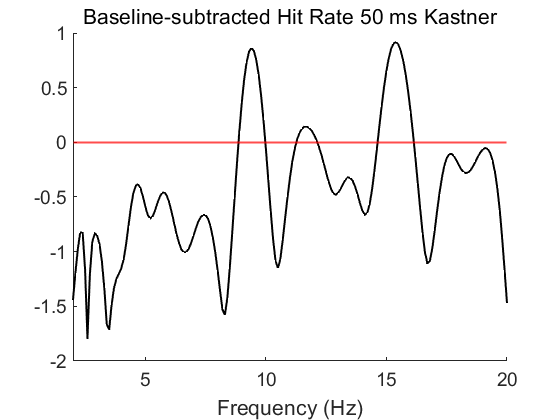


FFT_hitRateKastner50SubRandandZScore = (abs(FFT_hitRateKastner50) - FFT_hitRateKastner50Rand_Mn) ./ FFT_hitRateKastner50Rand_Sd;

figure
plot(xValsKastner, FFT_hitRateKastner50SubRandandZScore, "k", "LineWidth", 1.5)
hold on
yline(0, "r", "LineWidth", 1.5)
hold off
box off
xlim([2 20])
ax = gca;
ax.FontSize = 14;
title("Baseline-subtracted Hit Rate 50 ms Kastner", "FontSize", 16, "FontWeight", "normal")
xlabel("Frequency (Hz)", "FontSize", 16)

### 50 ms Kastner hit rate boostrap

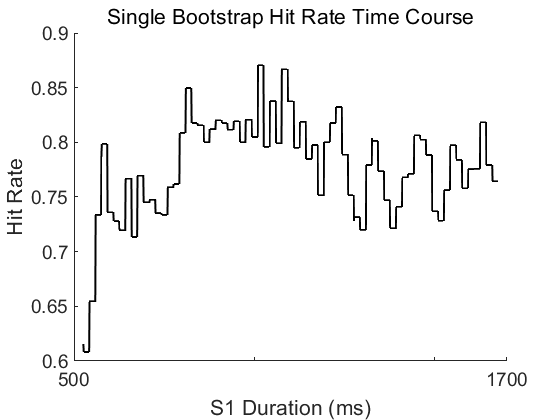

numBoostraps = 1000;
bootstrapVals = randi([1 length(validCorrect)], length(validCorrect), numBoostraps);
bootstrapCorrect = validCorrect(bootstrapVals);
bootstrapS1 = validS1(bootstrapVals);
hitRateKastner50Boot = nan(1150, 1);

for m = 1:numBoostraps
    for n = 1:1150
        windowTrials50 = bootstrapS1(:,m) >= window50(n) & bootstrapS1(:,m) <= window50(n) + 50;
        hitRateKastner50Boot(n, m) = sum(bootstrapCorrect(windowTrials50, m), "all") / sum(windowTrials50, "all");
    end
end

figure
plot(xValKastner50, hitRateKastner50Boot(:,1), "k", "LineWidth", 1.5)
box off
xticks([500 1000 1500 1700])
xticklabels([500, "", "", 1700])
xlim([500 1700])
ax = gca;
ax.FontSize = 14;
title("Single Bootstrap Hit Rate Time Course", "FontSize", 16, "FontWeight", "normal")
xlabel("S1 Duration (ms)", "FontSize", 16)
ylabel("Hit Rate", "FontSize", 16)

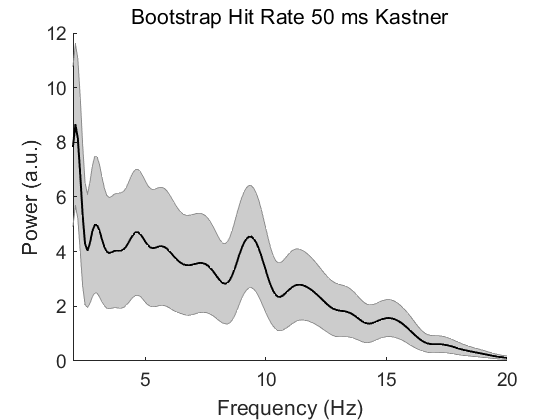


hitRateKastner50Boot = movmean(hitRateKastner50Boot, 25, 1);   % 25 point boxcar smoothing
hitRateKastner50BootWin = hitRateKastner50Boot .* hann(height(hitRateKastner50Boot));
hitRateKastner50BootWinPad = [hitRateKastner50BootWin; zeros(8850, numBoostraps)];

FFT_hitRateKastner50Boot = fft(hitRateKastner50BootWinPad);
FFT_hitRateKastner50Boot_Mn = mean(abs(FFT_hitRateKastner50Boot), 2);
FFT_hitRateKastner50Boot_Sd = std(abs(FFT_hitRateKastner50Boot), [], 2);

figure
plot(xValsKastner, FFT_hitRateKastner50Boot_Mn, "k", "LineWidth", 1.5)
hold on
shadedErrorBar(xValsKastner, FFT_hitRateKastner50Boot_Mn, FFT_hitRateKastner50Boot_Sd)
hold off
box off
xlim([2 20])
ax = gca;
ax.FontSize = 14;
xlabel("Frequency (Hz)", "FontSize", 16)
ylabel("Power (a.u.)", "FontSize", 16)
title("Bootstrap Hit Rate 50 ms Kastner", "FontSize", 16, "FontWeight", "normal")

### Collective Plotting

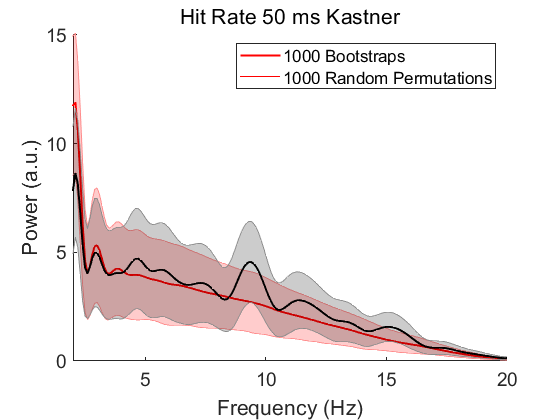

figure
plot(xValsKastner, FFT_hitRateKastner50Rand_Mn, "r", "LineWidth", 1.5)
hold on
shadedErrorBar(xValsKastner, FFT_hitRateKastner50Rand_Mn, FFT_hitRateKastner50Rand_Sd, 'LineProps', 'r')
plot(xValsKastner, FFT_hitRateKastner50Boot_Mn, "k", "LineWidth", 1.5)
shadedErrorBar(xValsKastner, FFT_hitRateKastner50Boot_Mn, FFT_hitRateKastner50Boot_Sd)
hold off
box off
xlim([2 20])
ax = gca;
ax.FontSize = 14;
xlabel("Frequency (Hz)", "FontSize", 16)
ylabel("Power (a.u.)", "FontSize", 16)
title("Hit Rate 50 ms Kastner", "FontSize", 16, "FontWeight", "normal")
legend(["1000 Bootstraps", "1000 Random Permutations"])